load('PredictionData312.mat')

reference_data = hourly312;

%edit the rest of the code to for 20 minute bursts
% of incoming flows


% INITIALIZING VARIABLES    
k = 23;                  % number of future steps to predict
M = 24;                  % length of a season in terms of data points is 12 (season = 1 year)

S = size(reference_data);
s1 = S(1)-k;
s2 = S(2);
actual = reference_data(1:s1,s2);
controlset = reference_data(1:S(1),s2);
control_set = controlset.';

Nseasons = floor(length(actual)/M);

% Smoothing constants (to be adjusted based on most recent training results)
alpha = 0.350097984;
beta = 0.005251386;
gamma = 6.85296E-09;

levels = zeros(s1,1);
trend = zeros(s1,1);
seasons = zeros(s1,1);

% -------------- CALCULATING INITIAL VALUES --------------------------------

% Calculation of initial level
levels(1) = sum(actual(1:M))/M;


% Calculation of initial trend for time series with additive seasonality
initialtrend = zeros(M,1);
for i = 1:M
    initialtrend(i) = (actual(i+M)-actual(i))/M;  
end

trend1 = sum(initialtrend)/M; 
trend(1) = trend1;                      % Assign the initial trend to the first entry in the trend array


% Calculation of season averages
Sav = zeros(1, Nseasons);
for i = 1:Nseasons
    av = zeros(1, M);
    for j = 1:M
        av(j) = actual((i-1)*M + j);
    end
    sumav = sum(av)/M;
    Sav(i) = sumav;                     % length of the Sav (season average) array should be Nseasons
end

% Calculation of initial season
initialseason = zeros(1, M);
tosum = zeros(1, Nseasons);
for j = 1:M
    for s = 1:Nseasons
        sumnew = actual((s-1)*M + j) - Sav(s);
        tosum(s) = sumnew;
    end
    initialseason(j) = sum(tosum)/Nseasons;   
end
seasons(1:M) = initialseason;
% ---------------------------------------------------------------------------------------

% HoltWinters Exponential Smoothing implementation

forecasts = [];                  % array of forecasts should be k points longer than the data to be forecasted

%forecasts(1) = A(1);
for i = 2:s1
                % A) Calculate and update levels (exponential smoothing)
    if i-1>=M                               % if the previous observation is beyond the first season (M observations)
        levels(i) = levelupdatehw(alpha,actual(i),seasons(i-M),levels(i-1),trend(i-1));                  % update the levels
    else                                    % if the previous observation is within the first season (within the first M observations)
        levels(i) = levelupdatehw(alpha,actual(i),0,levels(i-1),trend(i-1));                  % previous season = 0 / non-existent
    end
                % B) Update the trend smoothing)
    levelstep = levels(i) - levels(i-1);
    trend(i) = trendupdate(beta,levelstep,trend(i-1));        % update the trends
    
    if i-M>0                                % if beyond season 1, since Season 1 was already initialized above
        seasons(i) = seasonupdate(gamma,actual(i),levels(i),seasons(i-M));
    end

                % C) Update the forecast

    for f = 1:k
        if i+f-1>=M                              % if the future forecasts are beyond season 1
            forecasts(i+f) = (levels(i) + f*trend(i)) + seasons(i+f-M);      % additive seasonality HoltWinters Exponential Smoothing applied
        end 
    end
end

[rmse2, nrmse2] = calculate_rmse(control_set, forecasts, M);  % calling rmse function at bottom
rmse2

rmse2 = 40.8489

nrmse2

nrmse2 = 0.1644

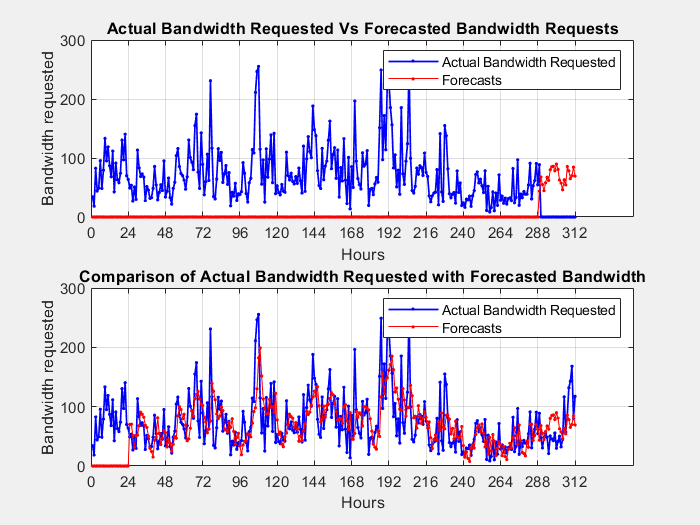


% ---------------- PLOTTING THE RESULTS -------------------------

hour = hourly312(:,1).';
actual_forplot = actual;                    % creating a new 'actual' array for plotting
actual_forplot((s1+1):(s1+k)) = 0;          % appending 0s to the end to bring the length up for plotting
predicted(1:s1) = 0;
predicted(s1:s1+k) = forecasts(s1:s1+k);

figure
set(gcf,'Visible','on')
subplot(2,1,1)
plot(hour,actual_forplot,"LineWidth",1,"Marker",".","Color","blue")
hold on
plot(hour,predicted,"Marker",".","Color","red") 
hold off
legend('Actual Bandwidth Requested','Forecasts')
title('Actual Bandwidth Requested Vs Forecasted Bandwidth Requests')
xlabel('Hours')
ylabel('Bandwidth requested')
set(gca,'xtick', 0:24:312)
grid on

subplot(2,1,2)
plot(hour,reference_data(:,2),"LineWidth",1,"Marker",".","Color","blue")
hold on
plot(hour,forecasts,"Marker",".","Color","red") 
hold off
legend('Actual Bandwidth Requested','Forecasts')
title('Comparison of Actual Bandwidth Requested with Forecasted Bandwidth')
xlabel('Hours')
ylabel('Bandwidth requested')
set(gca,'xtick', 0:24:312)
grid on

function [rmse, nrmse] = calculate_rmse(actual, predicted, szn_length)
    actual(1:szn_length) = [];        % excluding the first season from
    predicted(1:szn_length) = [];     % rmse calculations as no forecasts
    error = actual - predicted;       % were done in the first season.
    N = numel(error);
    err_sq = error.^2;
    err_sum = sum(err_sq);
    err_mean = err_sum/N;
    rmse = sqrt(err_mean);
    nrmse = rmse/(max(actual)-min(actual));
end
